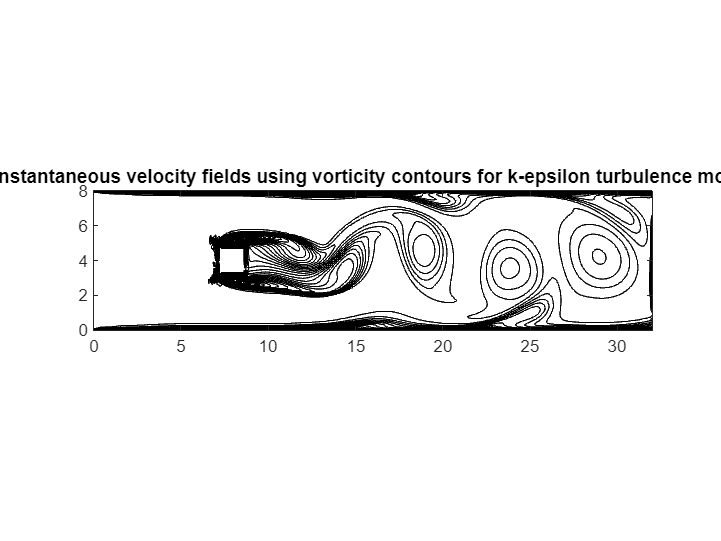

clc
clear
% data given in the daten file in the code given in assignment has data for square cylinder size 1.5*1.5 
% in this code same daten file data is used for 1.5 characteristic length   
% observed this issue after running the code, due to time constrain; the body
% size and location for k_epsilon and K_l models were unchanged and the
% values for RNS model was changed to match the value of the other 2
% models, i.e., the values were taken as the follwoing for all 3 models:
% 73, 88, 34, 49 and the values of the characteristics length was taken as
% 1.5 and simulations were run. All results of simulation were for char
% length of 1.5 only. No simulation were run for char length of
% The inputs corresponding to grid location of body(ia, ib, ja, jb) as per the given "Guidance" file is:
%   a. 73, 88, 34, 49 for k_epsilon
%   b. 73, 88, 34, 49 for k_l
%   c. 73, 86, 34, 49 for RNS
% simulation were not run for 1.0 char length
% However, given the assignment constrains,
% another set of calculation(only for Strouhal number) were done for characteristic length of 1.0 as
% well. Both the set of calculations only for Strouhal number have been done here.

X = 32;
NX = 320;
hx = X/NX;
Y = 8;
NY = 82;
hy = Y/NY;

%%%%%%%%%%%%%%% k_epsilon%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
addpath ("/MATLAB Drive/Post_processing_Files/kepsi")
load 'cl1000_kep.txt'
load 'cd1000_kep.txt'
load 'result_kep.txt'
load 'kepsi_fft_point_1.txt'
load 'kepsi_fft_point_15.txt'

t_cl_kepsi = cl1000_kep(:,1);
Cl_kepsi = cl1000_kep(:,2);
t_cd_keps = cd1000_kep(:,1);
Cd_kepsi = cd1000_kep(:,2);
u_Raw_kepsi = result_kep(:, 1);
v_Raw_kepsi = result_kep(:, 2);
%P2_kep = result_kep(:, 3);
%xk2_kep = result_kep(:, 4);
%d2_kep = result_kep(:, 5);


Vorticity_kepsilon = zeros(81, 321);
U_kepsilon = zeros(82, 322);
V_kepsilon = zeros(82, 322);
for i = 1:322
    i_min = (i-1)*82+1;
    i_max = (i-1)*82+82;
    U_colmn = u_Raw_kepsi(i_min:i_max);
    U_kepsilon (:,i) = U_colmn;
    V_colmn = v_Raw_kepsi(i_min:i_max);
    V_kepsilon (:,i) = V_colmn;
end

for i = 1:321
    for j =1:81
        Vorticity_kepsilon_x = (V_kepsilon(j, i+1)-V_kepsilon(j, i))/hx;
        Vorticity_kepsilon_y = (U_kepsilon(j+1, i)-U_kepsilon(j, i))/hy;
        Vorticity_kepsilon (j,i) = Vorticity_kepsilon_x-Vorticity_kepsilon_y;
    end
end

[x, y] = meshgrid(linspace(0, 32, 321), linspace(0, 8, 81));
contour(x,y,Vorticity_kepsilon, 225, 'LineColor', 'k')
xlim([0.0 32.0])
ylim([0.00 8.00])
axis equal
title('Instantaneous velocity fields using vorticity contours for k-epsilon turbulence model')

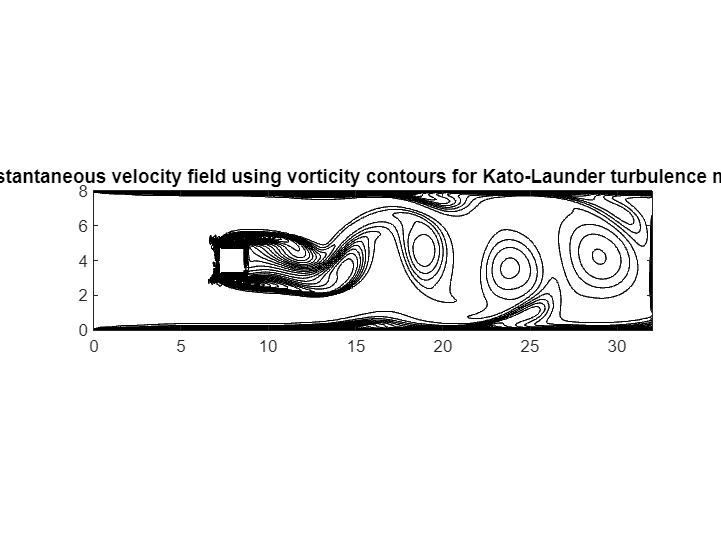


Cd_Raw_epsilon = Cd_kepsi(301:end);
Cd_average_kepsi = mean(Cd_Raw_epsilon);
Cl_Raw_epsi = Cl_kepsi(301:end);
Cl_average_kepsi = mean(Cl_Raw_epsi);

frequency_kepsi_1 = kepsi_fft_point_1(:,1);
mod_kepsi_1 = kepsi_fft_point_1(:,2);
max = 0;
for i = 1:length(mod_kepsi_1)
    if mod_kepsi_1(i)>max
        max = mod_kepsi_1(i);
        i_max = i;
    end
end
freq_max_kep_1 = mod_kepsi_1(i_max);
St_1_kep = frequency_kepsi_1(i_max)*1/1;

freq_kep_15 = kepsi_fft_point_15(:,1);
mod_kep_15 = kepsi_fft_point_15(:,2);
max = 0;
for i = 1:length(mod_kep_15)
    if mod_kep_15(i)>max
        max = mod_kep_15(i);
        i_max = i;
    end
end
freq_max_kep_15 = mod_kep_15(i_max);
%fprintf(" The strohual number for K_epsilon")
St_15_kep = freq_kep_15(i_max)*1.5/1;
%fprintf("St_15_kep = ",St_15_kep)
%%%%%%%%%% k_epsilon%%%%%

%%%%%% Kato-Launder%%%(Kala)%%%%%%
addpath ("/MATLAB Drive/Post_processing_Files/kl")
load 'cl1000_kl.txt'
load 'cd1000_kl.txt'
load 'result_kl.txt'
load 'kl_fft_point_1.txt'
load 'kl_fft_point_15.txt'

t_cl_kalau = cl1000_kl(:,1);
Cl_kalau = cl1000_kl(:,2);
t_cd_kalau = cd1000_kl(:,1);
Cd_kalau = cd1000_kl(:,2);
U_Raw_kalau = result_kl(:, 1);
V_Raw_kalau = result_kl(:, 2);
%P2_kalau = result_kl(:, 3);
%xk2_kalau = result_kl(:, 4);
%d2_kalau = result_kl(:, 5);

Vorticity_kalau = zeros(81, 321);
U_kalau = zeros(82, 322);
V_kalau = zeros(82, 322);
for i = 1:322
    i_min = (i-1)*82+1;
    i_max = (i-1)*82+82;
    U_colmn = U_Raw_kalau(i_min:i_max);
    U_kalau (:,i) = U_colmn;
    V_colmn = V_Raw_kalau(i_min:i_max);
    V_kalau (:,i) = V_colmn;
end

for i = 1:321
    for j =1:81
        Vorticity_kalau_x = (V_kalau(j, i+1)-V_kalau(j, i))/hx;
        Vorticity_kalau_y = (U_kalau(j+1, i)-U_kalau(j, i))/hy;
        Vorticity_kalau (j,i) = Vorticity_kalau_x-Vorticity_kalau_y;
    end
end

[x, y] = meshgrid(linspace(0, 32, 321), linspace(0, 8, 81));
contour(x,y,Vorticity_kalau, 225, 'LineColor', 'k')
xlim([0.0 32.0])
ylim([0.00 8.00])
axis equal
title('Instantaneous velocity field using vorticity contours for Kato-Launder turbulence model')

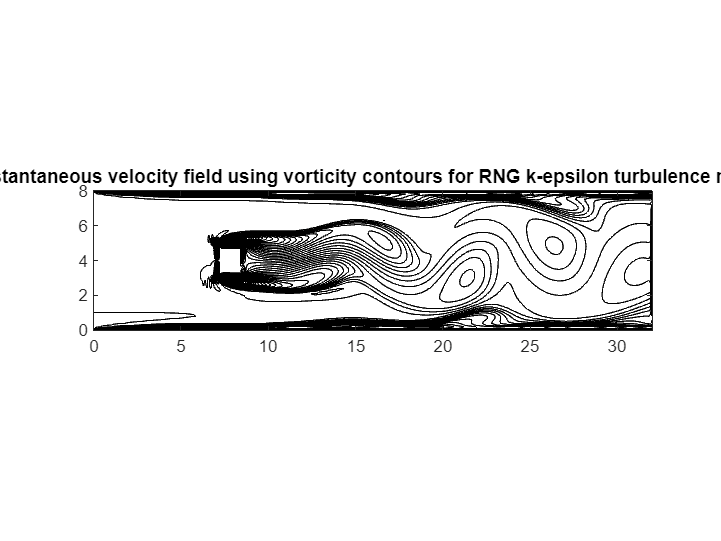


Cd_raw_kalau = Cd_kalau(301:end);
Cd_average_kalau = mean(Cd_raw_kalau);
Cl_Raw_kalau = Cl_kalau(301:end);
Cl_average_kalau = mean(Cl_Raw_kalau);

freq_kalau_1 = kl_fft_point_1(:,1);
mod_kalau_1 = kl_fft_point_1(:,2);
max = 0;
for i = 1:length(mod_kalau_1)
    if mod_kalau_1(i)>max
        max = mod_kalau_1(i);
        i_max = i;
    end
end
freq_max_kalau_1 = mod_kalau_1(i_max);
St_1_kalau = freq_kalau_1(i_max)*1/1;

freq_kalau_15 = kl_fft_point_15(:,1);
mod_kalau_15 = kl_fft_point_15(:,2);
max = 0;
for i = 1:length(mod_kalau_15)
    if mod_kalau_15(i)>max
        max = mod_kalau_15(i);
        i_max = i;
    end
end
freq_max_kl_15 = mod_kalau_15(i_max);
%fprintf(" The strohual number for Kato-Launder")
St_15_kl = freq_kalau_15(i_max)*1.5/1;
%%%%%% KaLa%%%%%%%%%%

%%%%%% RNG-K_espsilon%%%%%%%%%%%%%%%%%%%%%%%
addpath ("/MATLAB Drive/Post_processing_Files/rng")
load 'cl1000_rng.txt'
load 'cd1000_rng.txt'
load 'result_rng.txt'
load 'rng_fft_point_1.txt'
load 'rng_fft_point_15.txt'

t_cl_rng = cl1000_rng(:,1);
Cl_rng = cl1000_rng(:,2);
t_cd_rng = cd1000_rng(:,1);
Cd_rng = cd1000_rng(:,2);
U_Raw_rng = result_rng(:, 1);
V_Raw_rng = result_rng(:, 2);
%P2_rng = result_rng(:, 3);
%xk2_rng = result_rng(:, 4);
%d2_rng = result_rng(:, 5);

Vorticity_rng = zeros(81, 321);
U_rng = zeros(82, 322);
V_rng = zeros(82, 322);
for i = 1:322
    i_min = (i-1)*82+1;
    i_max = (i-1)*82+82;
    U_colmn = U_Raw_rng(i_min:i_max);
    U_rng (:,i) = U_colmn;
    V_colmn = V_Raw_rng(i_min:i_max);
    V_rng (:,i) = V_colmn;
end

for i = 1:321
    for j =1:81
        Vorticity_rng_x = (V_rng(j, i+1)-V_rng(j, i))/hx;
        Vorticity_rng_y = (U_rng(j+1, i)-U_rng(j, i))/hy;
        Vorticity_rng (j,i) = Vorticity_rng_x-Vorticity_rng_y;
    end
end

[x, y] = meshgrid(linspace(0, 32, 321), linspace(0, 8, 81));
contour(x,y,Vorticity_rng, 330, 'LineColor', 'k')
xlim([0.0 32.0])
ylim([0.00 8.00])
axis equal
title('Instantaneous velocity field using vorticity contours for RNG k-epsilon turbulence model')


Cd_Raw_rng = Cd_rng(301:end);
Cd_average_rng = mean(Cd_Raw_rng);
Cl_Raw_rng = Cl_rng(301:end);
Cl_average_rng = mean(Cl_Raw_rng);

frequency_rng_1 = rng_fft_point_1(:,1);
mod_rng_1 = rng_fft_point_1(:,2);
max = 0;
for i = 1:length(mod_rng_1)
    if mod_rng_1(i)>max
        max = mod_rng_1(i);
        i_max = i;
    end
end
frequency_max_rng_1 = mod_rng_1(i_max);
St_1_rng = frequency_rng_1(i_max)*1/1;

frequency_rng_15 = rng_fft_point_15(:,1);
mod_rng_15 = rng_fft_point_15(:,2);
max = 0;
for i = 1:length(mod_rng_15)
    if mod_rng_15(i)>max
        max = mod_rng_15(i);
        i_max = i;
    end
end
freq_max_rng_15 = mod_rng_15(i_max);
%fprintf(" The strohual number for Rng_k-epsilon")
St_15_rng = frequency_rng_15(i_max)*1.5/1;
%%%%%%%%%%%%%%%% RNG%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Table for different grids given
    values = {'k-epsilon', St_15_kep, Cd_average_kepsi, Cl_average_kepsi, freq_max_kep_15, 1.5, 3.1; 
              'KaLa', St_15_kl, Cd_average_kalau, Cl_average_kalau, freq_max_kl_15, 1.5,3.1;
              'RNG', St_15_rng, Cd_average_rng, Cl_average_rng, freq_max_rng_15, 1.5,3.3;
                'k-epsilon', St_1_kep, Cd_average_kepsi, Cl_average_kepsi, freq_max_kep_1, 1,3.1; 
              'KaLa', St_1_kalau, Cd_average_kalau, Cl_average_kalau, freq_max_kalau_1, 1,3.1;
              'RNG', St_1_rng, Cd_average_rng, Cl_average_rng, frequency_max_rng_1, 1,3.3;};
    Table = cell2table(values, 'VariableNames', {'Turbulence_Model', 'Strouhal Number', 'Cd (time averaged)', 'Cl (time averaged)', 'Max Amplitude', 'Char length considered','Recirculation length'})

Table = 6x7 table
    Turbulence Model    Strouhal No    Cd(time averaged)    Cl(time averaged)    max amplitude    Char length considered    Recirculation length
    ________________    ___________    _________________    _________________    _____________    ______________________    ____________________

     {'k-epsilon'}        0.19227           2.3876              0.0071024           4804.8                 1.5                      3.1         
     {'KaLa'     }        0.19227            2.387               0.007085           4785.2                 1.5                      3.1         
     {'RNG'      }        0.19227           2.1812              0.0034255           991.78                 1.5                      3.3         
     {'k-epsilon'}